%Read .dat files into a table for cleaning and processing
sittostand_jun_trial_01 = readtable("sit_to_stand_jun_trial_01.dat");

%cleaning columns for removing junk data: Annotations, Shank_L 1&2
sittostand_jun_01_clean = removevars(sittostand_jun_trial_01,{'Annotation','Annotation_1','Shank_L_1','Shank_L_2'});

%cleaning NaN values (removing rows?) using rmmissing
%% sittostand_jun_01_clean = rmmissing(sittostand_jun_trial_01);

%no NaN values in this set of data. Hence not implementing the rmmissing code
%figure1 = plot(sittostand_jun_01_clean,"Thigh_R","Thigh_R_1")

sittostand_jun_01_clean_1 = renamevars(sittostand_jun_01_clean,["Thigh_R","Shank_R","Foot_R","Thigh_L","Shank_L","Foot_L","Pelvis"],["Thigh_R_Time","Shank_R_Time","Foot_R_Time","Thigh_L_Time","Shank_L_Time","Foot_L_Time","Pelvis_Time"]);
sittostand_jun_01_clean_1 = renamevars(sittostand_jun_01_clean_1,["Shank_L_3","Shank_L_4","Shank_L_5","Shank_L_6","Shank_L_7","Shank_L_8","Shank_L_9","Shank_L_10","Shank_L_11"],["Shank_L_1","Shank_L_2","Shank_L_3","Shank_L_4","Shank_L_5","Shank_L_6","Shank_L_7","Shank_L_8","Shank_L_9"]);

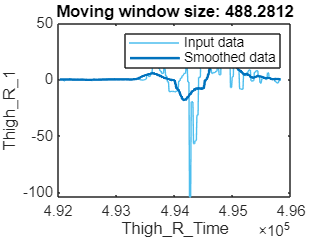

% Filtering for Thigh_R
% Smooth input data
[sittostand_jun_01_filtered_thigh_r,winSize] = smoothdata(sittostand_jun_01_clean_1, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Thigh_R_1","Thigh_R_2","Thigh_R_3","Thigh_R_4","Thigh_R_5", ...
    "Thigh_R_6","Thigh_R_7","Thigh_R_8","Thigh_R_9"], ...
    "SamplePoints",sittostand_jun_01_clean_1.Thigh_R_Time);

% Display results
figure
plot(sittostand_jun_01_clean_1.Thigh_R_Time,sittostand_jun_01_clean_1.Thigh_R_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(sittostand_jun_01_clean_1.Thigh_R_Time,sittostand_jun_01_filtered_thigh_r.Thigh_R_1,"SeriesIndex",1, ...
    "LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize));
legend
ylabel("Thigh_R_1","Interpreter","none")
xlabel("Thigh_R_Time","Interpreter","none")

clear winSize

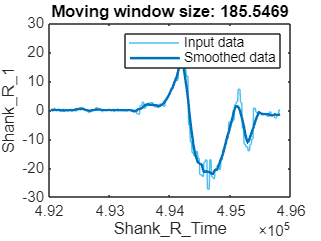

% Filtering for Shank_R
% Smooth input data
[sittostand_jun_01_filtered_shank_r,winSize2] = smoothdata(sittostand_jun_01_filtered_thigh_r, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Shank_R_1","Shank_R_2","Shank_R_3","Shank_R_4","Shank_R_5", ...
    "Shank_R_6","Shank_R_7","Shank_R_8","Shank_R_9"], ...
    "SamplePoints",sittostand_jun_01_filtered_thigh_r.Shank_R_Time);

% Display results
figure
plot(sittostand_jun_01_filtered_thigh_r.Shank_R_Time,sittostand_jun_01_filtered_thigh_r.Shank_R_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(sittostand_jun_01_filtered_thigh_r.Shank_R_Time,sittostand_jun_01_filtered_shank_r.Shank_R_1, ...
    "SeriesIndex",1,"LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize2));
legend
ylabel("Shank_R_1","Interpreter","none")
xlabel("Shank_R_Time","Interpreter","none")

clear winSize2

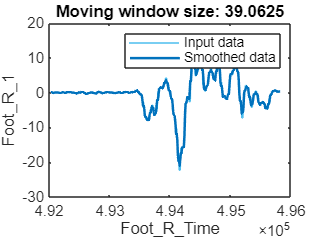

% Filtering for Foot_R
% Smooth input data
[sittostand_jun_01_filtered_foot_r,winSize3] = smoothdata(sittostand_jun_01_filtered_shank_r, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Foot_R_1","Foot_R_2","Foot_R_3","Foot_R_4","Foot_R_5", ...
    "Foot_R_6","Foot_R_7","Foot_R_8","Foot_R_9"], ...
    "SamplePoints",sittostand_jun_01_filtered_shank_r.Foot_R_Time);

% Display results
figure
plot(sittostand_jun_01_filtered_shank_r.Foot_R_Time,sittostand_jun_01_filtered_shank_r.Foot_R_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(sittostand_jun_01_filtered_shank_r.Foot_R_Time,sittostand_jun_01_filtered_foot_r.Foot_R_1, ...
    "SeriesIndex",1,"LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize3));
legend
ylabel("Foot_R_1","Interpreter","none")
xlabel("Foot_R_Time","Interpreter","none")

clear winSize3

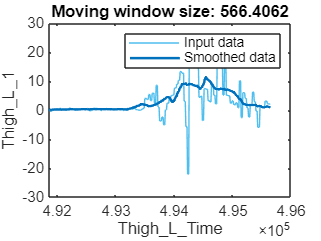

% Filtering for Thigh_L
% Smooth input data
[sittostand_jun_01_filtered_thigh_l,winSize4] = smoothdata(sittostand_jun_01_filtered_foot_r, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Thigh_L_1","Thigh_L_2","Thigh_L_3","Thigh_L_4","Thigh_L_5", ...
    "Thigh_L_6","Thigh_L_7","Thigh_L_8","Thigh_L_9"], ...
    "SamplePoints",sittostand_jun_01_filtered_foot_r.Thigh_L_Time);

% Display results
figure
plot(sittostand_jun_01_filtered_foot_r.Thigh_L_Time,sittostand_jun_01_filtered_foot_r.Thigh_L_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(sittostand_jun_01_filtered_foot_r.Thigh_L_Time,sittostand_jun_01_filtered_thigh_l.Thigh_L_1, ...
    "SeriesIndex",1,"LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize4));
legend
ylabel("Thigh_L_1","Interpreter","none")
xlabel("Thigh_L_Time","Interpreter","none")

clear winSize4

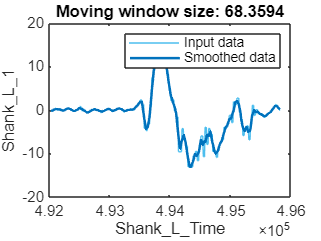

% Filtering for Shank_L
% Smooth input data
[sittostand_jun_01_filtered_shank_l,winSize5] = smoothdata(sittostand_jun_01_filtered_thigh_l, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Shank_L_1","Shank_L_2","Shank_L_3","Shank_L_4","Shank_L_5", ...
    "Shank_L_6","Shank_L_7","Shank_L_8","Shank_L_9"], ...
    "SamplePoints",sittostand_jun_01_filtered_thigh_l.Shank_L_Time);

% Display results
figure
plot(sittostand_jun_01_filtered_thigh_l.Shank_L_Time,sittostand_jun_01_filtered_thigh_l.Shank_L_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(sittostand_jun_01_filtered_thigh_l.Shank_L_Time,sittostand_jun_01_filtered_shank_l.Shank_L_1, ...
    "SeriesIndex",1,"LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize5));
legend
ylabel("Shank_L_1","Interpreter","none")
xlabel("Shank_L_Time","Interpreter","none")

clear winSize5

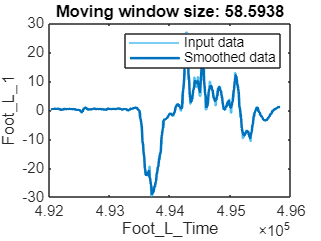

% Filtering for Foot_L
% Smooth input data
[sittostand_jun_01_filtered_foot_l,winSize6] = smoothdata(sittostand_jun_01_filtered_shank_l, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Foot_L_1","Foot_L_2","Foot_L_3","Foot_L_4","Foot_L_5", ...
    "Foot_L_6","Foot_L_7","Foot_L_8","Foot_L_9"], ...
    "SamplePoints",sittostand_jun_01_filtered_shank_l.Foot_L_Time);

% Display results
figure
plot(sittostand_jun_01_filtered_shank_l.Foot_L_Time,sittostand_jun_01_filtered_shank_l.Foot_L_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(sittostand_jun_01_filtered_shank_l.Foot_L_Time,sittostand_jun_01_filtered_foot_l.Foot_L_1, ...
    "SeriesIndex",1,"LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize6));
legend
ylabel("Foot_L_1","Interpreter","none")
xlabel("Foot_L_Time","Interpreter","none")

clear winSize6

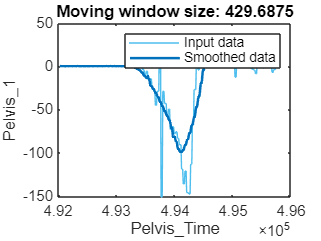

% Filtering for Pelvis
% Smooth input data
[sittostand_jun_01_filtered_final,winSize7] = smoothdata(sittostand_jun_01_filtered_foot_l, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Pelvis_1","Pelvis_2","Pelvis_3","Pelvis_4","Pelvis_5", ...
    "Pelvis_6","Pelvis_7","Pelvis_8","Pelvis_9"], ...
    "SamplePoints",sittostand_jun_01_filtered_foot_l.Pelvis_Time);

% Display results
figure
plot(sittostand_jun_01_filtered_foot_l.Pelvis_Time,sittostand_jun_01_filtered_foot_l.Pelvis_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(sittostand_jun_01_filtered_foot_l.Pelvis_Time,sittostand_jun_01_filtered_final.Pelvis_1, ...
    "SeriesIndex",1,"LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize7));
legend
ylabel("Pelvis_1","Interpreter","none")
xlabel("Pelvis_Time","Interpreter","none")

clear winSize7

% Process TR section
TR_tables = Sliding_Window(sittostand_jun_01_filtered_final, 'Thigh_R');

% Process SR section
SR_tables = Sliding_Window(sittostand_jun_01_filtered_final, 'Shank_R');

%Process FR section
FR_tables = Sliding_Window(sittostand_jun_01_filtered_final, 'Foot_R');

%Process TL section
TL_tables = Sliding_Window(sittostand_jun_01_filtered_final, 'Thigh_L');

%Process SL section
SL_tables = Sliding_Window(sittostand_jun_01_filtered_final, 'Shank_L');

%Process FL section
FL_tables = Sliding_Window(sittostand_jun_01_filtered_final, 'Foot_L');

%Process P section
P_tables = Sliding_Window(sittostand_jun_01_filtered_final, 'Pelvis');

% Combine results
Var_Names = {'Max', 'Min', 'Mean', 'RMS', 'MaxGrad', 'STD', 'ZC'};
for v = 1:length(Var_Names)
    Combined_Table = [TR_tables.(Var_Names{v}), SR_tables.(Var_Names{v}), FR_tables.(Var_Names{v}), TL_tables.(Var_Names{v}), SL_tables.(Var_Names{v}), FL_tables.(Var_Names{v}), P_tables.(Var_Names{v})];
    assignin('base', ['Sit_' Var_Names{v} '_J1'], Combined_Table);
end

%Discared Codes - due to bugs or optimisation or redundancy

%Sampling
% Fs = 100;
% sample_rate = 50;
% Thigh_R_Time_Sampled = sittostand_jun_01_filtered_final.Thigh_R_Time(1:Fs/sample_rate:end);
% Thigh_R_Sampled = sittostand_jun_01_filtered_final.Thigh_R_1(1:Fs/sample_rate:end);
% plot(Thigh_R_Time_Sampled,Thigh_R_Sampled)

% %ColumnNames
% sittostand_jun_01_colnames = sittostand_jun_01_filtered_final.Properties.VariableNames;

% % Initialize tables to store the data
% Sit_Max_J1 = table();
% Sit_Min_J1 = table();
% Sit_Mean_J1 = table();
% Sit_RMS_J1 = table();
% Sit_MaxGrad_J1 = table();
% Sit_STD_J1 = table();
% Sit_ZC_J1 = table();
% 
% window_length = 40;
% l = length(sittostand_jun_01_filtered_final.Thigh_R_Time) - window_length;
% n = 1;
% num_blocks = 9;
% 
% % Pre-allocate result arrays for each parameter
% for i = 1:7:l
%     % Temporary storage for the current iteration's row
%     current_row_Max = [];
%     current_row_Min = [];
%     current_row_Mean = [];
%     current_row_RMS = [];
%     current_row_MaxGrad = [];
%     current_row_STD = [];
%     current_row_ZC = [];
% 
%     % Loop over each block and store the results
%     for block_num = 1:num_blocks
%         % Dynamically construct the block variable
%         block_data = sittostand_jun_01_filtered_final.(['Thigh_R_' num2str(block_num)])(i:i + window_length);
% 
%         % Call the parameters function and store the results
%         [max_TR_J1, min_TR_J1, mean_TR_J1, rms_TR_J1, maxgrad_TR_J1, std_TR_J1, zc_TR_J1] = parameters(block_data);
% 
%         % Store the current block's result in the temporary row storage
%         current_row_Max = [current_row_Max, max_TR_J1];
%         current_row_Min = [current_row_Min, min_TR_J1];
%         current_row_Mean = [current_row_Mean, mean_TR_J1];
%         current_row_RMS = [current_row_RMS, rms_TR_J1];
%         current_row_MaxGrad = [current_row_MaxGrad, maxgrad_TR_J1];
%         current_row_STD = [current_row_STD, std_TR_J1];
%         current_row_ZC = [current_row_ZC, zc_TR_J1];
%     end
% 
%     % After processing all blocks, add the results as a new row to each table
%     % Create dynamic column names for each block (for each specific table)
%     column_names_Max = arrayfun(@(x) ['Max_TR' num2str(x)], 1:num_blocks, 'UniformOutput', false);
%     column_names_Min = arrayfun(@(x) ['Min_TR' num2str(x)], 1:num_blocks, 'UniformOutput', false);
%     column_names_Mean = arrayfun(@(x) ['Mean_TR' num2str(x)], 1:num_blocks, 'UniformOutput', false);
%     column_names_RMS = arrayfun(@(x) ['RMS_TR' num2str(x)], 1:num_blocks, 'UniformOutput', false);
%     column_names_MaxGrad = arrayfun(@(x) ['MaxGrad_TR' num2str(x)], 1:num_blocks, 'UniformOutput', false);
%     column_names_STD = arrayfun(@(x) ['STD_TR' num2str(x)], 1:num_blocks, 'UniformOutput', false);
%     column_names_ZC = arrayfun(@(x) ['ZC_TR' num2str(x)], 1:num_blocks, 'UniformOutput', false);
% 
%     % Add the current row to the respective tables with dynamic column names
%     Sit_Max_J1 = [Sit_Max_J1; array2table(current_row_Max, 'VariableNames', column_names_Max)];
%     Sit_Min_J1 = [Sit_Min_J1; array2table(current_row_Min, 'VariableNames', column_names_Min)];
%     Sit_Mean_J1 = [Sit_Mean_J1; array2table(current_row_Mean, 'VariableNames', column_names_Mean)];
%     Sit_RMS_J1 = [Sit_RMS_J1; array2table(current_row_RMS, 'VariableNames', column_names_RMS)];
%     Sit_MaxGrad_J1 = [Sit_MaxGrad_J1; array2table(current_row_MaxGrad, 'VariableNames', column_names_MaxGrad)];
%     Sit_STD_J1 = [Sit_STD_J1; array2table(current_row_STD, 'VariableNames', column_names_STD)];
%     Sit_ZC_J1 = [Sit_ZC_J1; array2table(current_row_ZC, 'VariableNames', column_names_ZC)];
% 
%     n = n + 1;
% end


% % Initialize variables
% window_length = 40;
% l = length(sittostand_jun_01_filtered_final.Thigh_R_Time) - window_length;
% num_blocks = 9;
% num_rows = floor(l / 7) + 1;
% 
% % Preallocate tables
% var_names = {'Max', 'Min', 'Mean', 'RMS', 'MaxGrad', 'STD', 'ZC'};
% tables = struct();
% for v = 1:length(var_names)
%     column_names = arrayfun(@(x) [var_names{v} '_TR' num2str(x)], 1:num_blocks, 'UniformOutput', false);
%     tables.(var_names{v}) = array2table(zeros(num_rows, num_blocks), 'VariableNames', column_names);
% end
% 
% % Main processing loop
% for row = 1:num_rows
%     i = (row - 1) * 7 + 1;
% 
%     % Process all blocks at once
%     block_data = arrayfun(@(x) sittostand_jun_01_filtered_final.(['Thigh_R_' num2str(x)])(i:i + window_length), 1:num_blocks, 'UniformOutput', false);
% 
%     % Call parameters function once for all blocks
%     [max_TR, min_TR, mean_TR, rms_TR, maxgrad_TR, std_TR, zc_TR] = cellfun(@parameters, block_data, 'UniformOutput', false);
% 
%     % Store results in preallocated tables
%     for v = 1:length(var_names)
%         tables.(var_names{v}){row, :} = cell2mat(eval([lower(var_names{v}) '_TR']));
%     end
% end
% 
% % Assign tables to workspace variables
% for v = 1:length(var_names)
%     assignin('base', ['Sit_' var_names{v} '_J1'], tables.(var_names{v}));
% end


% %Thigh_L 
% window_length = 40;
% 
% l = length(sittostand_jun_01_filtered_final.Thigh_L)-window_length;
% n = 1;
% for i=1:7:l
%     Block1 = sittostand_jun_01_filtered_final.Thigh_L_1(i:i+window_length);
%     Block2 = sittostand_jun_01_filtered_final.Thigh_L_2(i:i+window_length);
%     Block3 = sittostand_jun_01_filtered_final.Thigh_L_3(i:i+window_length);
%     Block4 = sittostand_jun_01_filtered_final.Thigh_L_4(i:i+window_length);
%     Block5 = sittostand_jun_01_filtered_final.Thigh_L_5(i:i+window_length);
%     Block6 = sittostand_jun_01_filtered_final.Thigh_L_6(i:i+window_length);
%     Block7 = sittostand_jun_01_filtered_final.Thigh_L_7(i:i+window_length);
%     Block8 = sittostand_jun_01_filtered_final.Thigh_L_8(i:i+window_length);
%     Block9 = sittostand_jun_01_filtered_final.Thigh_L_9(i:i+window_length);
% 
%     [max28(n),min28(n),mean28(n),rms28(n),maxgrad28(n),std28(n),zc28(n)] = parameters(Block1);
%     [max29(n),min29(n),mean29(n),rms29(n),maxgrad29(n),std29(n),zc29(n)] = parameters(Block2);
%     [max30(n),min30(n),mean30(n),rms30(n),maxgrad30(n),std30(n),zc30(n)] = parameters(Block3);
%     [max31(n),min31(n),mean31(n),rms31(n),maxgrad31(n),std31(n),zc31(n)] = parameters(Block4);
%     [max32(n),min32(n),mean32(n),rms32(n),maxgrad32(n),std32(n),zc32(n)] = parameters(Block5);
%     [max33(n),min33(n),mean33(n),rms33(n),maxgrad33(n),std33(n),zc33(n)] = parameters(Block6);
%     [max34(n),min34(n),mean34(n),rms34(n),maxgrad34(n),std34(n),zc34(n)] = parameters(Block7);
%     [max35(n),min35(n),mean35(n),rms35(n),maxgrad35(n),std35(n),zc35(n)] = parameters(Block8);
%     [max36(n),min36(n),mean36(n),rms36(n),maxgrad36(n),std36(n),zc36(n)] = parameters(Block9);
% 
%     n = n+1;
% end


% %Shank_L 
% window_length = 40;
% l = length(sittostand_jun_01_filtered_final.Shank_L)-window_length;
% n = 1;
% for i=1:7:l
%     Block1 = sittostand_jun_01_filtered_final.Shank_L_3(i:i+window_length);
%     Block2 = sittostand_jun_01_filtered_final.Shank_L_4(i:i+window_length);
%     Block3 = sittostand_jun_01_filtered_final.Shank_L_5(i:i+window_length);
%     Block4 = sittostand_jun_01_filtered_final.Shank_L_6(i:i+window_length);
%     Block5 = sittostand_jun_01_filtered_final.Shank_L_7(i:i+window_length);
%     Block6 = sittostand_jun_01_filtered_final.Shank_L_8(i:i+window_length);
%     Block7 = sittostand_jun_01_filtered_final.Shank_L_9(i:i+window_length);
%     Block8 = sittostand_jun_01_filtered_final.Shank_L_10(i:i+window_length);
%     Block9 = sittostand_jun_01_filtered_final.Shank_L_11(i:i+window_length);
% 
%     [max37(n),min37(n),mean37(n),rms37(n),maxgrad37(n),std37(n),zc37(n)] = parameters(Block1);
%     [max38(n),min38(n),mean38(n),rms38(n),maxgrad38(n),std38(n),zc38(n)] = parameters(Block2);
%     [max39(n),min39(n),mean39(n),rms39(n),maxgrad39(n),std39(n),zc39(n)] = parameters(Block3);
%     [max40(n),min40(n),mean40(n),rms40(n),maxgrad40(n),std40(n),zc40(n)] = parameters(Block4);
%     [max41(n),min41(n),mean41(n),rms41(n),maxgrad41(n),std41(n),zc41(n)] = parameters(Block5);
%     [max42(n),min42(n),mean42(n),rms42(n),maxgrad42(n),std42(n),zc42(n)] = parameters(Block6);
%     [max43(n),min43(n),mean43(n),rms43(n),maxgrad43(n),std43(n),zc43(n)] = parameters(Block7);
%     [max44(n),min44(n),mean44(n),rms44(n),maxgrad44(n),std44(n),zc44(n)] = parameters(Block8);
%     [max45(n),min45(n),mean45(n),rms45(n),maxgrad45(n),std45(n),zc45(n)] = parameters(Block9);
% 
%     n = n+1;
% end